start_stim = P.OFF_dur *P.fs;
stop_stim = (P.OFF_dur +P.ON_dur) * P.fs;

stimulus = -P(1).mean_movement(start_stim:stop_stim-1);
stimulus_model = stimulus(1:8*fs);
stimulus_test = stimulus(8*fs+1:end);

mean_gcfr = P.avg_gcfr(start_stim:stop_stim);
mean_gcfr_model = mean_gcfr(1:8*fs);
mean_gcfr_test_set = mean_gcfr(8*fs+1:end-1);


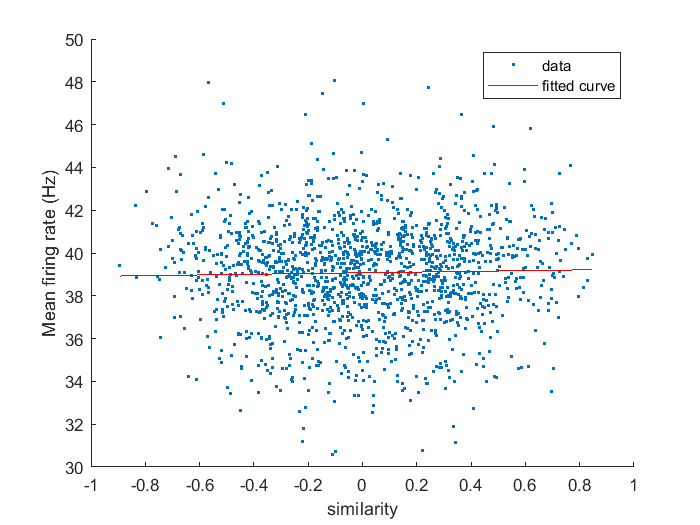

winLength = 30e-3*fs;
shift = 5e-3*fs;
similarity_STA = [];
FR = [];

for i = 1:shift:length(stimulus_model)-winLength
    stimPattern = stimulus_model(i:i+winLength);
    similarity = dot(stimPattern, STA)/(norm(stimPattern)*norm(STA));
    similarity_STA = [similarity_STA similarity];
    
    FR = [FR mean_gcfr_model(i+winLength)];
end

figure;
% scatter(similarity_STA, FR, 3, "black", "filled");
f = fit(similarity_STA', FR', 'poly1');
hold on;
plot(f, similarity_STA, FR, '.');
ylabel('Mean firing rate (Hz)');
xlabel('similarity');

## Prediction

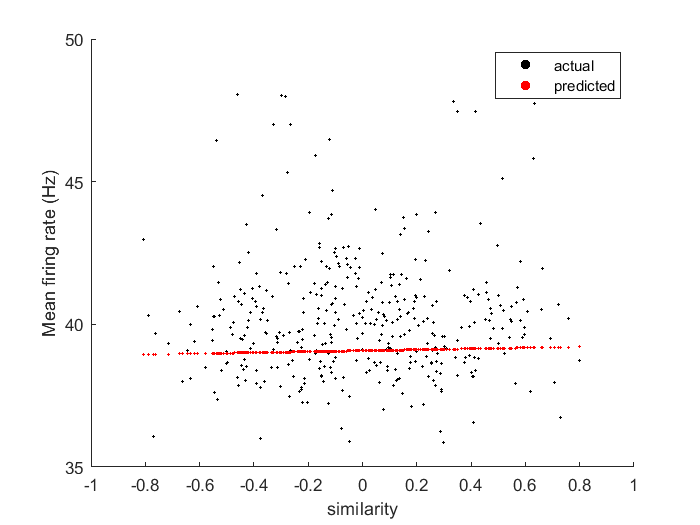

similarity_STA_test = [];
FR_actual = [];
FR_pred = [];

for i = 1:shift:length(stimulus_test)-winLength
    stimPattern = stimulus_test(i:i+winLength);
    similarity = dot(stimPattern, STA)/(norm(stimPattern)*norm(STA));
    similarity_STA_test = [similarity_STA_test similarity];
    
    FR_actual = [FR_actual mean_gcfr_model(i+winLength)];
    FR_pred = [FR_pred f(similarity)];
end

figure;
scatter(similarity_STA_test, FR_actual, 3, "black", "filled"); hold on;
scatter(similarity_STA_test, FR_pred, 3, "red", "filled");
legend('actual', 'predicted');

hold on;
ylabel('Mean firing rate (Hz)');
xlabel('similarity');